# **Target Point Approach**

clear; clc;

mu = 0.0121505856;

% ===== Nominal halo initial state =====
data = readmatrix('halo_L1_one_period_nondim.csv');
t_nom = data(:,1);
X_nom  = data(:,2:7);
x0_nom = X_nom(1,:)';

T_orbit = 2.7499;      % approximate halo period
dt = 1e-3;

x_ref = X_nom;
t_ref = t_nom;

Phi0 = eye(6);

[t_stm, Phi_vec] = ode45(@(t,Phi) compute_STM(t,Phi,mu,t_nom,X_nom), ...
                         t_nom, Phi0(:));

Phi_ref = zeros(6,6,length(t_stm));

for k = 1:length(t_stm)
    Phi_ref(:,:,k) = reshape(Phi_vec(k,:),6,6);
end

disp('STM computed along nominal orbit');

STM computed along nominal orbit



% ===== STEP 2: Stationkeeping Simulation =====
t_final = 30*T_orbit;

t_min   = 0.2 * T_orbit;   % minimum time between burns
p_min   = 5e-6;             % minimum position deviation (nondimensional)
v_min   = 2e-5;             % minimum burn magnitude (nondimensional)

corr_interval = 0.25*T_orbit;
target_offsets = [0.2 0.4 0.6]*T_orbit;

last_burn_time = -inf;
prev_error_mag = 0;

Q  = 1.5*eye(3);

R  = diag([40 1 0.1]);
S  = diag([1 20 0.1]);
T  = diag([0.1 1 10]);

Rv = 0.5*eye(3);
Sv = 0.5*eye(3);
Tv = 0.5*eye(3); 

%Rv = diag([1e2 1e-2 1e-3]);
%Sv  = diag([1e-2 1 0]);
%Tv  = diag([1e-3 1e-2 1e-1]);

Wcell = {
    1*blkdiag(R, Rv)
    0.3*blkdiag(S, Sv)
    0.25*blkdiag(T, Tv)
};

% injection error
x = x_ref(1,:)' + [5e-5; -3e-5; 2e-5; 0; 0; 0];

t = 0;
next_corr_time = corr_interval;

time_hist = [];
state_hist = [];
dv_total = 0;
pos_error_hist = [];
burn_positions = [];
burn_times = [];

while t < t_final
    
    % propagate one step
    [~, xtmp] = ode45(@(t,x) cr3bp(t,x,mu), [t t+dt], x);
    x = xtmp(end,:)';
    t = t + dt;

    time_hist(end+1,1) = t;
    state_hist(end+1,:) = x';

    % ===== correction =====
    if t >= next_corr_time

        B = [zeros(3); eye(3)];

        M1 = zeros(3,3);
        M2 = zeros(3,1);

        % interpolate nominal state
        x_nom = interp1(t_ref, x_ref, mod(t,T_orbit),'linear')';
        dx = x - x_nom;

        pos_error_mag = norm(dx(1:3));

        pos_error_hist(end+1) = pos_error_mag;

        for k = 1:length(target_offsets)
            t1 = mod(t, T_orbit);
            t2 = t1 + target_offsets(k);   % NO mod here

            Phi = getSTM(t1, t2, t_ref, Phi_ref);
      
            Hk = Phi * B;            % 6x3

            % predicted deviation
            dx_pred = Phi * dx;      % 6x1

            Wk = Wcell{k};           % 6x6 weighting

            M1 = M1 + Hk' * Wk * Hk;
            M2 = M2 + Hk' * Wk * dx_pred;

        end

        lambda = 1e-6;
        dv = -((Q + M1 + lambda*eye(3)) \ M2);
        
        if any(isnan(dv)) || any(isinf(dv)) || norm(dv) > 1e-2
            warning('Skipping unstable burn');
            next_corr_time = next_corr_time + corr_interval;
            continue;
        end

        time_condition = (t - last_burn_time) >= t_min;
        deviation_condition = pos_error_mag >= p_min;

        if time_condition && deviation_condition
            if norm(dv) >= v_min
                x(4:6) = x(4:6) + dv;
                dv_total = dv_total + norm(dv);
                last_burn_time = t;

                % Store burn position
                burn_positions(end+1,:) = x(1:3)';

                fprintf('Burn at t = %.3f, dv = %.3e\n', t, norm(dv));
            end

        else
            prev_error_mag = pos_error_mag;
        end

        next_corr_time = next_corr_time + corr_interval;
    end
end

Burn at t = 0.688, dv = 8.491e-04
Burn at t = 1.375, dv = 3.061e-04
Burn at t = 2.063, dv = 5.499e-05
Burn at t = 2.750, dv = 4.831e-04
Burn at t = 3.438, dv = 2.957e-04
Burn at t = 4.125, dv = 2.916e-04
Burn at t = 4.813, dv = 3.685e-04
Burn at t = 5.500, dv = 4.621e-04
Burn at t = 6.188, dv = 3.266e-04
Burn at t = 6.875, dv = 2.943e-04
Burn at t = 7.563, dv = 4.406e-04
Burn at t = 8.250, dv = 3.925e-04
Burn at t = 8.938, dv = 3.452e-04
Burn at t = 9.625, dv = 2.947e-04
Burn at t = 10.313, dv = 4.712e-04
Burn at t = 11.000, dv = 3.521e-04
Burn at t = 11.688, dv = 3.543e-04
Burn at t = 12.375, dv = 2.941e-04
Burn at t = 13.063, dv = 4.848e-04
Burn at t = 13.750, dv = 3.306e-04
Burn at t = 14.437, dv = 3.583e-04
Burn at t = 15.125, dv = 2.922e-04
Burn at t = 15.812, dv = 4.891e-04
Burn at t = 16.500, dv = 3.218e-04
Burn at t = 17.187, dv = 3.599e-04
Burn at t = 17.875, dv = 2.915e-04
Burn at t = 18.562, dv = 4.926e-04
Burn at t = 19.250, dv = 3.164e-04
Burn at t = 19.937, dv = 3.609e-04

am = 384400;   % km scaling

% --- Metrics ---
max_error_km = max(pos_error_hist) * am;
rms_error_km = sqrt(mean(pos_error_hist.^2)) * am;

dv_total_mps = dv_total * 1024;

fprintf('\n===== PERFORMANCE METRICS =====\n');


===== PERFORMANCE METRICS =====


fprintf('Total Delta-V     = %.3f m/s\n', dv_total_mps);

Total Delta-V     = 44.849 m/s


fprintf('Max Position Error = %.3f km\n', max_error_km);

Max Position Error = 113.696 km


fprintf('RMS Position Error = %.3f km\n', rms_error_km);

RMS Position Error = 69.609 km


fprintf('Number of Burns    = %d\n', length(pos_error_hist));

Number of Burns    = 120


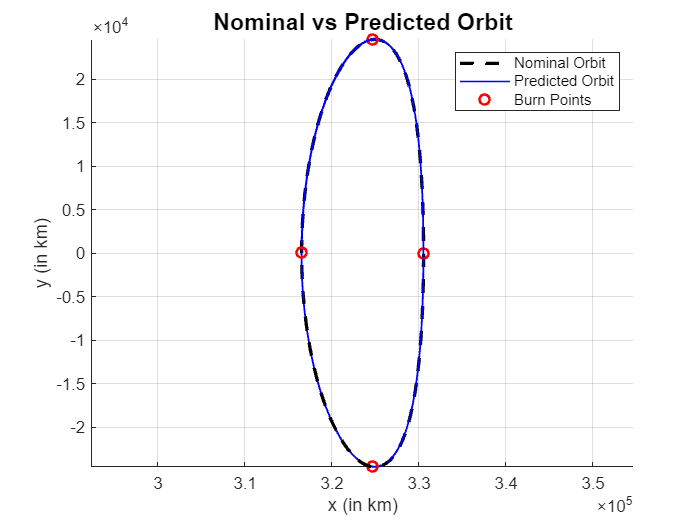

am = 384400;
% ===== Plot =====
figure; hold on; grid on; axis equal;

% Nominal orbit
plot3(x_ref(:,1)*am, x_ref(:,2)*am, x_ref(:,3)*am,  'k--', 'LineWidth', 2);

% Stationkept orbit
plot3(state_hist(:,1)*am, state_hist(:,2)*am, state_hist(:,3)*am, 'b-','LineWidth', 1);

% Convert to km
burn_positions_km = burn_positions * am;

% Plot burn points
plot3(burn_positions_km(:,1), ...
      burn_positions_km(:,2), ...
      burn_positions_km(:,3), ...
      'ro', 'MarkerSize', 6, 'LineWidth', 1.5);

legend('Nominal Orbit','Predicted Orbit','Burn Points');

xlabel('x (in km)');
ylabel('y (in km)');
zlabel('z (in km)');
title('Nominal vs Predicted Orbit', 'FontSize', 14);

## Functions

function Phi = getSTM(t0, t1, t_ref, Phi_ref)

T = t_ref(end);

% wrap times into one orbit
t0 = mod(t0, T);
t1 = mod(t1, T);

% interpolate STM at t0 and t1
Phi0 = interpSTM(t0, t_ref, Phi_ref);
Phi1 = interpSTM(t1, t_ref, Phi_ref);

% STM from t0 to t1
Phi = Phi1 / Phi0;

end

function Phi = interpSTM(t, t_ref, Phi_ref)

Phi = zeros(6,6);

for i = 1:6
    for j = 1:6
        Phi(i,j) = interp1(t_ref, squeeze(Phi_ref(i,j,:)), t, 'linear');
    end
end

end

function dPhidt = compute_STM(t, Phi_vec, mu, t_nom, X_nom)

Phi = reshape(Phi_vec,6,6);

% interpolate nominal state
x = interp1(t_nom, X_nom, t, 'linear')';
x = x(:);

% compute A matrix
A = compute_A(x, mu);

% STM differential equation
dPhidt = A * Phi;
dPhidt = dPhidt(:);

end

function dxdt = cr3bp(~, x, mu)

r1 = sqrt((x(1)+mu)^2 + x(2)^2 + x(3)^2);
r2 = sqrt((x(1)-1+mu)^2 + x(2)^2 + x(3)^2);

dxdt = zeros(6,1);

dxdt(1)=x(4);
dxdt(2)=x(5);
dxdt(3)=x(6);

dxdt(4)=2*x(5)+x(1) ...
 -(1-mu)*(x(1)+mu)/r1^3 ...
 -mu*(x(1)-1+mu)/r2^3;

dxdt(5)=-2*x(4)+x(2) ...
 -(1-mu)*x(2)/r1^3 ...
 -mu*x(2)/r2^3;

dxdt(6)=-(1-mu)*x(3)/r1^3 ...
 -mu*x(3)/r2^3;

end

function A = compute_A(x, mu)

r1 = sqrt((x(1)+mu)^2 + x(2)^2 + x(3)^2);
r2 = sqrt((x(1)-1+mu)^2 + x(2)^2 + x(3)^2);

Uxx = 1 ...
-(1-mu)*(1/r1^3 - 3*(x(1)+mu)^2/r1^5) ...
- mu*(1/r2^3 - 3*(x(1)-1+mu)^2/r2^5);

Uyy = 1 ...
-(1-mu)*(1/r1^3 - 3*x(2)^2/r1^5) ...
- mu*(1/r2^3 - 3*x(2)^2/r2^5);

Uzz = ...
-(1-mu)*(1/r1^3 - 3*x(3)^2/r1^5) ...
- mu*(1/r2^3 - 3*x(3)^2/r2^5);

Uxy = 3*(1-mu)*(x(1)+mu)*x(2)/r1^5 ...
     +3*mu*(x(1)-1+mu)*x(2)/r2^5;

Uxz = 3*(1-mu)*(x(1)+mu)*x(3)/r1^5 ...
     +3*mu*(x(1)-1+mu)*x(3)/r2^5;

Uyz = 3*(1-mu)*x(2)*x(3)/r1^5 ...
     +3*mu*x(2)*x(3)/r2^5;

A = zeros(6);

A(1:3,4:6) = eye(3);

A(4,1)=Uxx; A(4,2)=Uxy; A(4,3)=Uxz; A(4,5)=2;
A(5,1)=Uxy; A(5,2)=Uyy; A(5,3)=Uyz; A(5,4)=-2;
A(6,1)=Uxz; A(6,2)=Uyz; A(6,3)=Uzz;

end